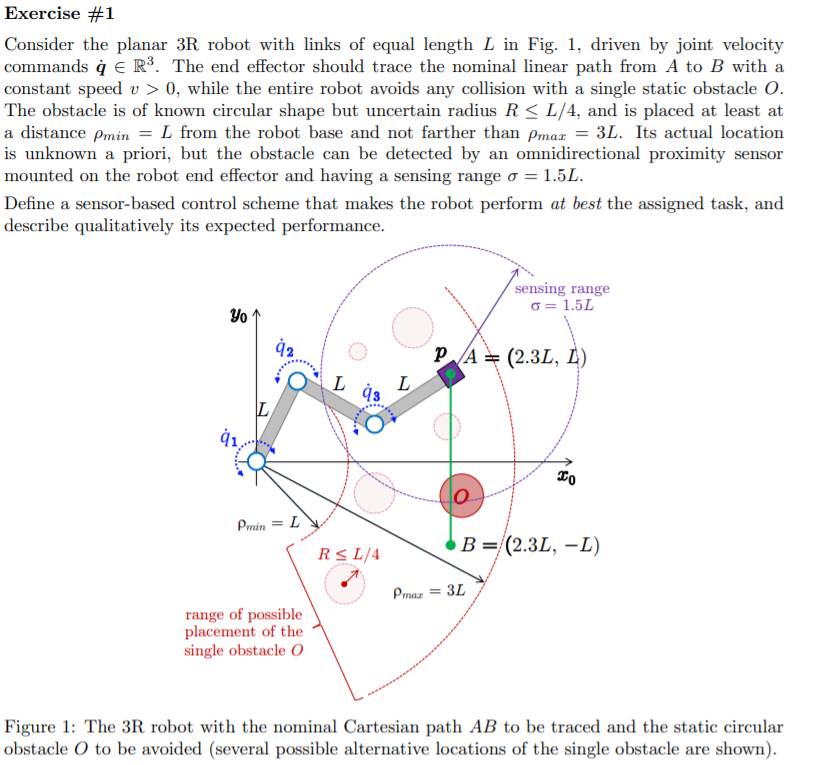

%done by hand


## 2

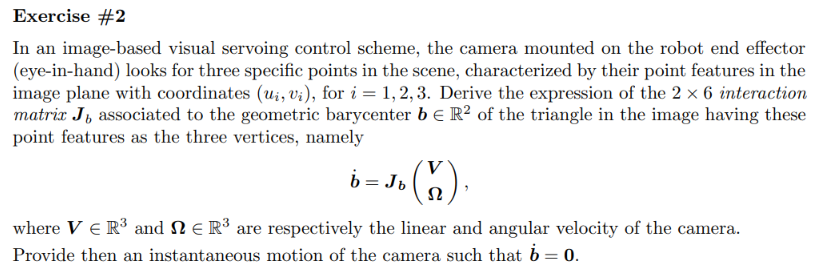

% clc;clear;
% [J_camera,velocities,V,OMEGA]=gen_interaction_matrix(2)

J_camera = 1×1 cell array
    {2×6 sym}


J_camera = 1×2 cell array
    {2×6 sym}    {2×6 sym}


J_camera = 1×2 cell array
    {2×6 sym}    {2×6 sym}


velocities = 1×2 cell array
    {1×1 struct}    {1×1 struct}


$$V = \left(\begin{array}{c} V_{1}\\ V_{2}\\ V_{3} \end{array}\right)$$

$$OMEGA = \left(\begin{array}{c} \Omega_{1}\\ \Omega_{2}\\ \Omega_{3} \end{array}\right)$$

% J_b=(J_camera{1}+J_camera{2})/2

$$J\_b = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{1} & 0 & \frac{u_{1}}{2\,Z_{1}}+\frac{u_{2}}{2\,Z_{2}} & \sigma_{3}+\sigma_{2} & -\lambda -\frac{{u_{1}}^{2}}{2\,\lambda }-\frac{{u_{2}}^{2}}{2\,\lambda } & \frac{v_{1}}{2}+\frac{v_{2}}{2}\\ 0 & \sigma_{1} & \frac{v_{1}}{2\,Z_{1}}+\frac{v_{2}}{2\,Z_{2}} & \lambda +\frac{{v_{1}}^{2}}{2\,\lambda }+\frac{{v_{2}}^{2}}{2\,\lambda } & -\sigma_{3}-\sigma_{2} & -\frac{u_{1}}{2}-\frac{u_{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{\lambda }{2\,Z_{1}}-\frac{\lambda }{2\,Z_{2}}\\ \sigma_{2}=\frac{u_{2}\,v_{2}}{2\,\lambda }\\ \sigma_{3}=\frac{u_{1}\,v_{1}}{2\,\lambda } \end{array}$$

% % J_b=(J_camera{1}+J_camera{2}+J_camera{3})/3
% OMEGA=[0,0,0]' 

OMEGA =      0
     0
     0


% vel_=J_b*[V;OMEGA]

$$vel\_ = \left(\begin{array}{c} V_{3}\,\left(\frac{u_{1}}{2\,Z_{1}}+\frac{u_{2}}{2\,Z_{2}}\right)-V_{1}\,\left(\frac{\lambda }{2\,Z_{1}}+\frac{\lambda }{2\,Z_{2}}\right)\\ V_{3}\,\left(\frac{v_{1}}{2\,Z_{1}}+\frac{v_{2}}{2\,Z_{2}}\right)-V_{2}\,\left(\frac{\lambda }{2\,Z_{1}}+\frac{\lambda }{2\,Z_{2}}\right) \end{array}\right)$$

% resn=(simplify(null(J_b))) %one ofthis solutions works well also

$$resn = \begin{array}{l} \left(\begin{array}{cccc} \frac{Z_{1}\,u_{2}+Z_{2}\,u_{1}}{\lambda \,\left(Z_{1}+Z_{2}\right)} & \sigma_{1} & -\frac{Z_{1}\,Z_{2}\,\left(2\,\lambda^{2}+{u_{1}}^{2}+{u_{2}}^{2}\right)}{\sigma_{2}} & \frac{Z_{1}\,Z_{2}\,\left(v_{1}+v_{2}\right)}{\lambda \,\left(Z_{1}+Z_{2}\right)}\\ \frac{Z_{1}\,v_{2}+Z_{2}\,v_{1}}{\lambda \,\left(Z_{1}+Z_{2}\right)} & \frac{Z_{1}\,Z_{2}\,\left(2\,\lambda^{2}+{v_{1}}^{2}+{v_{2}}^{2}\right)}{\sigma_{2}} & -\sigma_{1} & -\frac{Z_{1}\,Z_{2}\,\left(u_{1}+u_{2}\right)}{\lambda \,\left(Z_{1}+Z_{2}\right)}\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{Z_{1}\,Z_{2}\,\left(u_{1}\,v_{1}+u_{2}\,v_{2}\right)}{\sigma_{2}}\\ \sigma_{2}=\lambda^{2}\,\left(Z_{1}+Z_{2}\right) \end{array}$$

% res1=simplify(J_b*resn(:,1))

$$res1 = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

% % J_b(1,1)

$$ans = -\frac{\lambda }{3\,Z_{1}}-\frac{\lambda }{3\,Z_{2}}-\frac{\lambda }{3\,Z_{3}}$$

% % J_b(1,3)

$$ans = \frac{u_{1}}{3\,Z_{1}}+\frac{u_{2}}{3\,Z_{2}}+\frac{u_{3}}{3\,Z_{3}}$$

% % simplify(J_b(1,3)/J_b(1,1))

$$ans = -\frac{Z_{1}\,Z_{2}\,u_{3}+Z_{1}\,Z_{3}\,u_{2}+Z_{2}\,Z_{3}\,u_{1}}{\lambda \,\left(Z_{1}\,Z_{2}+Z_{1}\,Z_{3}+Z_{2}\,Z_{3}\right)}$$

% % res=solve([vel_==0;V~=0],[V])

res = struct with fields:
    V_1: [1×1 sym]
    V_2: [1×1 sym]
    V_3: [1×1 sym]


% % % res.Omega_1
% % res.V_1

$$ans = \frac{Z_{1}\,Z_{2}\,u_{3}+Z_{1}\,Z_{3}\,u_{2}+Z_{2}\,Z_{3}\,u_{1}}{\lambda \,\left(Z_{1}\,Z_{2}+Z_{1}\,Z_{3}+Z_{2}\,Z_{3}\right)}$$

% % res.V_2

$$ans = \frac{Z_{1}\,Z_{2}\,v_{3}+Z_{1}\,Z_{3}\,v_{2}+Z_{2}\,Z_{3}\,v_{1}}{\lambda \,\left(Z_{1}\,Z_{2}+Z_{1}\,Z_{3}+Z_{2}\,Z_{3}\right)}$$

% % res.V_3

$$ans = 1$$